## **BEATING THE STOCK MARKET USING SEASONAL INVESTING**

#### **Ryan Krechel - SYS 6014 - Updated March 21, 2020**

**INTRODUCTION**

For this project, I intend to create a model for seasonal investing to find a way to beat a buy-and-hold investment strategy. In theory, there are certain market trends that repeat at the same time each year. For instance, the beginning of December tends to be a time when investors sell off stocks to cover the cost of taxes which generally causes a decrease in the stock market. If an investor is aware of this trend, he or she should choose to invest in less aggressive accounts (perhaps bonds) at this time of the year to protect assets and not lose any money. My goal is to find other trends based on historical data and identify a strategy for trading on a day to day basis within a calendar year to maximize returns.

**BUILDING THE STRATEGY**

This project is built around a day-trading approach. In this way, a strategy is defined as instructions to invest in a particular ETF as a day trade for each trading day over an entire calendar year. The decision maker (a random investor interested in seasonal investing) technically uses this analysis to make a decision every day, but each decision is made from historical data for that particular calendar day. In this way, the decision analysis tool gains new information on a year-to-year basis and not a day-to-day basis. Therefore, the decision maker can essentially define a strategy on December 31 for the following calendar year and stick to it until the following December 31.

**DATA SELECTION AND CHOOSING FUNDS**

For the analysis, I have chosen 7 Vanguard exchange-traded funds (ETF) that cover differing sectors of the market and differing investment strategies. They each have different inception dates, with the newest being created in 2008. Therefore, to create a level playing field, data was only collected from 2008 to 2019.

The following ETFs were chosen and used for this analysis:

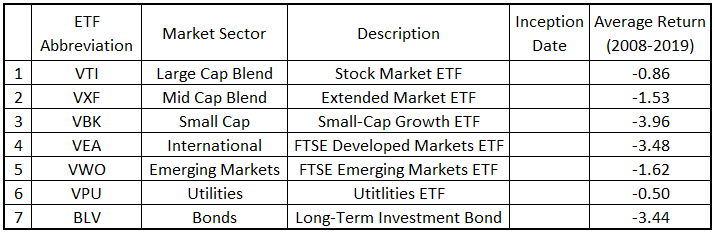

Clearly, the average for each fund is actually quite poor. This is largely due to a brutal 2008 recession that drives the averages down, but this fact actually presents the perfect opportunity to prove if this optimization method works since investing in any particular fund does not guarantee a good return based on averages.

**DEFINING SUCCESS**

In general, the goal is to beat a traditional buy-and-hold strategy, which is defined as choosing to invest in any one the ETFs used in this analysis for the entire calendar year. The following table presents the individual performance of each fund for a common range of years, 2008-2019.

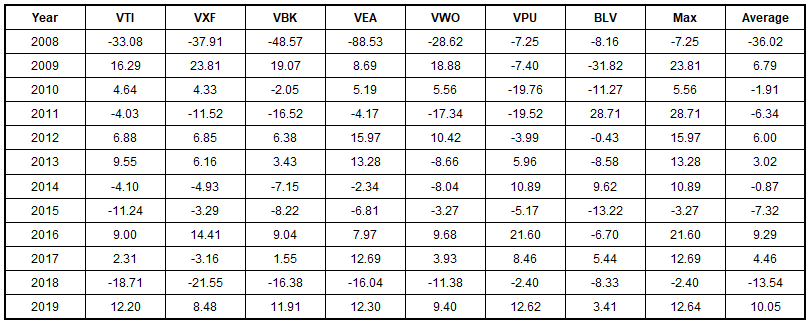

Since new data is collected very slowly (it takes an entire calendar year to add a full data set addition), success will be determined by taking a snapshot in time sometime in the past. For instance, data from 2008 to 2018 can be used to create a strategy that the decision maker could have chosen on December 31, 2018 to use during 2019. Since that data has already been collected, it can be used to test if the strategy defined at that time would have worked. The goal is to prove that this method works before actually investing an real money.

To be considered a success, the strategy identified by this analysis needs to at least perform better than the average of returns for each ETF of a given calendar year. Ideally, the strategy should also identify a way of obtaining a return greater than the best performing fund for that year. Based on the situational example in the previous paragraph and data from the table above, the strategy chosen for 2019 must produce a return greater than 10.05%, but ideally would produce a return greater than 12.62% (which would have been achieved by leaving money in the VPU ETF for the entirety of 2019).

**ACTION SET**[**¶**](http://localhost:8888/notebooks/Desktop/SYS%206014%20Data%20Project/Final%20Project/Ryan%20Krechel%20SYS%206014%20Final%20Project%20(Working).ipynb#ACTION-SET)

The decision-maker's action set *A* is a complete itemization of all the options available to the decision-maker, from which the decision-maker selects a unique choice. There are 8 decisions in this model shown in the following table.

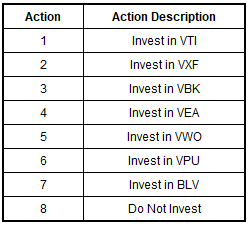

**STATE SPACE, PARAMTER SPACE, AND DATA GENERATING PROCESS**[**¶**](http://localhost:8888/notebooks/Desktop/SYS%206014%20Data%20Project/Final%20Project/Ryan%20Krechel%20SYS%206014%20Final%20Project%20(Working).ipynb#STATE-SPACE,-PARAMTER-SPACE,-AND-DATA-GENERATING-PROCESS)

Data will be collected using Yahoo's share price history tool from 2008-2019. Preprocessing will be done on the "open" and "close" prices to convert the share prices into daily losses or gains. This will be produced and uploaded into Matlab code with the corresponding dates to use in the analysis.

SOMETHING ABOUT WHAT STATE AND PARAMETER SPACE IS................

Once the raw data is uploaded into Matlab, it will need to be sorted by date and by gain/loss. The code will be written to assess January 2nd as a specific decision node with historical data from all other January 2nd data points. Within this day's worth of data, there will be a set of positive gains and a set of negative losses. In this way, I will be able to track success of each historical success of each ETF for any given day, both in likelihood of positive return and average value of positive/negative return. The code will repeat this process for each calendar day to develop a "strategy" for the year.

**PRIOR BELIEFS**[**¶**](http://localhost:8888/notebooks/Desktop/SYS%206014%20Data%20Project/Final%20Project/Ryan%20Krechel%20SYS%206014%20Final%20Project%20(Working).ipynb#PRIOR-BELIEFS)

It is a commonly known fact that the stock market tends to average an 8% return (although the particular ETFs used in this analysis average much less over the chosen year). However, this is an average for the year, and the decision maker doeS not know much about any particular day. For the sake of simplicity, I will assume no prior beliefs and take the percentage of a particular investment returning a positive gain on any given day as 50%. Similarly, the percentage of an investment in any ETF returning a loss is 50%

However, there are many years of data available in this analysis to apply and overwrite these ignorant prior beliefs to build a more reliable model. The actual percentages will be calculated in the processing code.

**PAYOFFS**[**¶**](http://localhost:8888/notebooks/Desktop/SYS%206014%20Data%20Project/Final%20Project/Ryan%20Krechel%20SYS%206014%20Final%20Project%20(Working).ipynb#PAYOFFS)

The payoffs will change based on the data set being observed and will be calculated directly using the historical data. For instance, in a situation where data from 2008 to 2018 is used, up to 11 different data points could exist for each calendar day (depending on where weekends fall because weekends are non-trading days with no data). For each calendar day, the data points will be separated by positive, negative, and net-zero return. The positive days will be averaged to find the positive payoff, and the negative days will be averaged to find the negative payoff.

**UTILITY FUNCTION AND DECISION MAKING PROCESS**[**¶**](http://localhost:8888/notebooks/Desktop/SYS%206014%20Data%20Project/Final%20Project/Ryan%20Krechel%20SYS%206014%20Final%20Project%20(Working).ipynb#UTILITY-FUNCTION-AND-DECISION-MAKING-PROCESS)

The utility function is generally defined as follows:

*�*EU(ETF) = (AvgPosReturn)⋅(PercPosReturn)+(AvgNegReturn)⋅(PercNegReturn)

For any given calendar day, this utility function will be calculated for each ETF. The model will make a decision simply based on the highest utility function available for each calendar day.

Here is an example from data collected from 2008 to 2018 for January 2, the first trading day of the year.

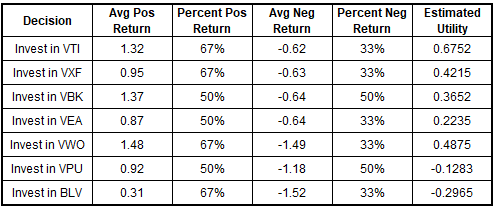

Therefore, based on the analysis of the data available for January 2, 2008-2018, the optimal ETF to invest in on January 2, 2019 is VTI.

It is important to note that the chance of a positive return and the chance of a negative return does not necessarily have to add up to 1. There is a chance of an ETF returning no net gain or loss, and it is important to include this annomally in the code if it shows up in the data. In fact, this was relavent for the data set above because the change of positive and negative return of investing in VEA was not equal to 1, so there was a day in the data set that had no net gain or loss.

**DATA ANALYSIS WITH MATLAB**[**¶**](http://localhost:8888/notebooks/Desktop/SYS%206014%20Data%20Project/Final%20Project/Ryan%20Krechel%20SYS%206014%20Final%20Project%20(Working).ipynb#DATA-ANALYSIS-WITH-MATLAB)

1) Start by importing each .csv file containing pre-processed data of daily returns for all seven ETFs. Create a matrix called "ETF" to hold all of the data in one place with a common reference name and populate it with the ETF data. Also, import another matrix that holds a data set created to store a "calendar" for later data processing. It will be important later to sort through the trading data and pair information by like days.

ETF = zeros(3020,4,7);
VTI = csvread('VTI1.csv'); ETF(:,:,1) = VTI(:,:);
VXF = csvread('VXF2.csv'); ETF(:,:,2) = VXF(:,:);
VBK = csvread('VBK3.csv'); ETF(:,:,3) = VBK(:,:);
VEA = csvread('VEA4.csv'); ETF(:,:,4) = VEA(:,:);
VWO = csvread('VWO5.csv'); ETF(:,:,5) = VWO(:,:);
VPU = csvread('VPU6.csv'); ETF(:,:,6) = VPU(:,:);
BLV = csvread('BLV7.csv'); ETF(:,:,7) = BLV(:,:);
Dates = csvread('YearlyData.csv');

2) To test the code, I built in the option to choose the range of years to use in data analysis. By changing these variables below, different scenarios can be run to test the effectiveness of the method. This is how the decision maker can simulate a decision in the past. For the purposes of this paper, the decision maker is sorting from 2008 to 2018 to make a decision about what strategy to follow for 2019. At the end of the code, 2019 will be navigated using the strategy to assess the performance of the methodology.

StartYear=2008;
EndYear=2018;

3) Create a matrix to hold the averaged data for each year, both for positive and negative, and populate with the data.

- Column 1 = month

- Column 2 = day of the month

- Column 3 = percentage of days

- Column 4 = average return for those days

PosDays = zeros(366,4,7); PosDays(:,1:2,1) = Dates(:,:);
NegDays = zeros(366,4,7); NegDays(:,1:2,1) = Dates(:,:);

for fund = 1:7
    for day = 1:366
        %create temporary variables to use in assessing data as positive
        %and negative for each calendar day
        PosETFcount=0; PosETFtotal=0; NegETFcount=0; NegETFtotal=0; ZeroETFcount=0;
        for data = 1:size(ETF,1)
            %Go through each date in ETF and see if it matches the calendar
            %date that is in my second for loop
            if(ETF(data,1,fund)==PosDays(day,1,1) && ETF(data,2,fund)==PosDays(day,2,1))
                %if between years of interest and value is positive
                if(ETF(data,3,fund)>=StartYear && ETF(data,3,fund)<=EndYear && ETF(data,4,fund)>0)
                    %count number of days of positive return
                    PosETFcount=PosETFcount+1;
                    %keep the total value to get average at the end
                    PosETFtotal=PosETFtotal+ETF(data,4,fund);
                end
                %if between years of interest and value is negative
                if(ETF(data,3,fund)>=StartYear && ETF(data,3,fund)<=EndYear && ETF(data,4,fund)<0)
                    %count number of negative days
                    NegETFcount=NegETFcount+1;
                    %keep the total value to get average at the end
                    NegETFtotal=NegETFtotal+ETF(data,4,fund);
                end
                %if between years of interest and value is 0
                if(ETF(data,3,fund)>=StartYear && ETF(data,3,fund)<=EndYear && ETF(data,4,fund)==0)
                    %count number of net-zero days
                    ZeroETFcount=ZeroETFcount+1;
                end         
            end 
        end
        
        %add up how many trading days there were for those years
        TotalETFdays=PosETFcount+NegETFcount+ZeroETFcount;
        
        %only run the code below if the total trading days was >0
        %important because the code runs even for holidays which are never
        %trading days
        if TotalETFdays>0
            %calculate the percent of days return was positive
            PosDays(day,3,fund)=PosETFcount/TotalETFdays;
            %if there are any positive days, solve the average pos return
            if PosETFcount>0
                PosDays(day,4,fund)=PosETFtotal/PosETFcount;
            end
            %calculate the percent of days return was negative
            NegDays(day,3,fund)=NegETFcount/TotalETFdays;
            %if there are any negative days, solve the average neg return
            if NegETFcount>0
                NegDays(day,4,fund)=NegETFtotal/NegETFcount; %average positive
            end
        end
    end
end

4) Solve the utility function to use in the decision making process. The Utility matrix has 12 columns.

- Columns 1-7 = estimated utility for each ETF in the same order as ETF matrix

- Column 8 = all zeros to represent utility of decision 8 (do not trade)

- Columns 9-10 = date information (9 = month, 10 = day of month)

- Column 11 = decision number (1-8) with the highest estimated utility

- Column 12 = corresponding estimated utility value of the optimal decision

5) Implement a rolling average into the decision making process. Use the UtilityAvg matrix to store the average of the current desicion day and the previous three decision days. This allows the opportunity to make a decision based on what was also happening leading up to the decision day. The data is held in a small matrix and the index and value are pulled out. ******************************8

Utility = zeros(366,12); Utility(:,9:10) = PosDays(:,1:2);

for day = 1:366
    %calculate the utility for each etf on each day
    %Utility = (perc pos)(avg pos value) + (perc neg)(avg neg value)
    Utility(day,1)=PosDays(day,3,1)*PosDays(day,4,1)+NegDays(day,3,1)*NegDays(day,4,1);
    Utility(day,2)=PosDays(day,3,2)*PosDays(day,4,2)+NegDays(day,3,2)*NegDays(day,4,2);
    Utility(day,3)=PosDays(day,3,3)*PosDays(day,4,3)+NegDays(day,3,3)*NegDays(day,4,3);
    Utility(day,4)=PosDays(day,3,4)*PosDays(day,4,4)+NegDays(day,3,4)*NegDays(day,4,4);
    Utility(day,5)=PosDays(day,3,5)*PosDays(day,4,5)+NegDays(day,3,5)*NegDays(day,4,5);
    Utility(day,6)=PosDays(day,3,6)*PosDays(day,4,6)+NegDays(day,3,6)*NegDays(day,4,6);
    Utility(day,7)=PosDays(day,3,7)*PosDays(day,4,7)+NegDays(day,3,7)*NegDays(day,4,7);
    
    %solve maximum utility and identify the decision choice
    %column 11 holds the etf number, 12 holds corresponding estimated utility
    [Utility(day,12) Utility(day,11)]=max(Utility(day,1:8));
    %if the date is a holiday, force decision to be "do not trade"
    if sum(Utility(day,1:7))==0
        Utility(day,11) = 8;
    end
end

6) Sum up the total estimated utility and print it out.This theoretically represents the return that the decision maker can expect for the next year.

TotalEstimatedUtility = sum(Utility(:,12))

TotalEstimatedUtility = 115.5105

7) Check the actual return for all years in the data set 2008-2019 based on the strategy that was just defined in step 4. The matrix "YearReturns" is created and used to hold the data. 

- Columns 1-2 = date information, both month and day

- Columns 3-7 = no information

- Columns 8-19 = returns for each day based on the defined strategy

YearReturns = zeros(366,19); YearReturns(:,1:2)=Utility(:,9:10);
%go through each day for every year to find the actual return of
%theoretically following the strategy just solved for
for year = 8:19
    for day = 1:366
        for data = 1:3020
            %make sure the code accesses the correct data by date
            if(ETF(data,1,1)==YearReturns(day,1) && ETF(data,2,1)==YearReturns(day,2) ...
                    && ETF(data,3,1)==2000+year && Utility(day,11)<8)
                %populate value with what would have been chosen given the
                %strategy was followed exactly
                YearReturns(day,year) = ETF(data,4,Utility(day,11));
            end
        end
    end
end

8) Print out the results of the strategy if used for the past years (in this case, 2008-2018). Also print the results of the strategy if followed "in the future". The code will work to analyze and solve any stretch of years of data, but in this case it will only be printing out the results of 2019 based on the example.

PerformanceByYearPast=zeros(2,EndYear-2008+1);
PerformanceByYearPast(1,:)=2008-2000:EndYear-2000;
for year = 1:length(PerformanceByYearPast)
    PerformanceByYearPast(2,year)=sum(YearReturns(:,2008-2000+year-1));
end
%print it out
PerformanceByYearPast

PerformanceByYearPast =     8.0000    9.0000   10.0000   11.0000   12.0000   13.0000   14.0000   15.0000   16.0000   17.0000   18.0000
  234.2823  118.0784   55.6176  107.0671   61.4920   30.2221   50.8631   58.6260   67.8805   33.3414   58.8083



%check the years in the future after EndYear
%this only runs if your search used data before 2019
if(EndYear<2019)
    PerformanceByYearFuture=zeros(2,2019-EndYear);
    PerformanceByYearFuture(1,:)=EndYear-2000+1:2019-2000;
    for year = 1:2019-EndYear
        PerformanceByYearFuture(2,year)=sum(YearReturns(:,year+EndYear-2000));
    end
    PerformanceByYearFuture
end

PerformanceByYearFuture =    19.0000
   10.7349


9) Also print out the returns of each individual ETF using the buy-and-hold approach used as the benchmark in this project. The description of what it says is as follow:

- Column 1 = year

- Column 2 = VTI

- Column 3 = VXF

- Column 4 = VBK

- Column 5 = VEA

- Column 6 = VWO

- Column 7 = VPU

- Column 8 = BLV

if(EndYear<2019)
    FutureYearsETF_BuyHold=zeros(2019-EndYear,8);
    FutureYearsETF_BuyHold(:,1)=EndYear-2000+1:2019-2000;
    for year = EndYear+1:2019
        firstIndex = find(ETF(:,3,1)==year,1,'first');
        lastIndex = find(ETF(:,3,1)==year,1,'last');
        for ETFnum=1:7
            FutureYearsETF_BuyHold(year-EndYear,ETFnum+1)=...
                sum(ETF(firstIndex:lastIndex,4,ETFnum));
        end
    end
    %print out the data
    FutureYearsETF_BuyHold
end

FutureYearsETF_BuyHold =    19.0000   12.1955    8.4811   11.9115   12.3005    9.4018   12.6247    3.4094


**EXPLANATION OF RESULTS AND FURTHER EVALUATION**

Based on the example set up in this report, the method was only partially successful. The strategy created using data from 2008 to 2018 resulted in a 2019 return of 10.73%. This is greater than the average return of the buy-and-hold ETF strategies (10.05%), but is less than the best performing individual strategy (VPU, 12.64%).

This is a disappointing result, but only represents one actual decision. In an attempt to validate the methodology of seasonal investing, the analysis was also run for many other scenarios; the results of which are displayed in the following table. It shows the results of the year following a decision using data from a certain stretch of years. For instance, the example from this report is found in the top right corner, since it was solved by searching from 2008 (Row 1) to 2018 (Column 8) and displays the results of following the defined strategy in 2019. Success is shown using a color code where a green box represents a result that beat the average and the best buy-and-hold strategy (successful), yellow represents a result that only beat the average (partially successful), and red represents a result that was worse than both (unsuccessful). Results are only displayed if there were at least four years of data to use in building the strategy.

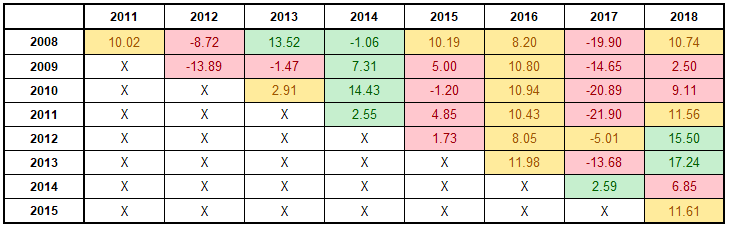

Of the 36 scenarios evaluated, 8 strategies were successful (22%), 13 were partially successful (36%), and 15 were unsuccessful (42%). This isn't exactly groundbreaking, and it would likely take more data to verify if the 58% overall chance of beating the average is actually statistically relavent.

Furthermore, there are trends in the data demonstrated by the color coding that tell more of a story. The 2014 column shows all green results, which means that the seasonal investment strategy beat all ETFs, regardless of the years used to collect data. Similarly, the 2015 column has mostly yellow results, regardless of data set. This is also prevalent in the 2016 and 2017 columns, which are dominated by yellow and red respectively. It seems to show that the results of the investment strategies have more to do with the random and unpredictable performance of the stock market for a given year than the actual data used to derive a strategy. If the data was actually making a difference, the successes would be concentrated in the top right of the table, which would represent scenarios where many years of data was used to define the strategy.

#### SUMMARY AND CONCLUSION

In conclusion, the methodology used in this project for seasonal investing does not work. It was not able to consistently define a strategy that would produce investment gains greater than a simplistic buy-and-hold investment strategy. The 36 scenarios evaluated in this paper showed only a 58% success rate of beating the average returns of buy-and-hold, but the successful scenarios follow no discernable trend and are mostly grouped within certain years of investing, regardless of the years used to collect data. Since the amount of data used to create a strategy is not correlated to the success of the strategy, the seasonal investment strategy used in this project cannot be effective.

An investor (aka, decision maker) would have similar success by picking a single ETF to invest in. In addition, the investor could save a lot of time and effort by simply choosing to invest in any individual ETF for the whole year. The seasonal investment strategies in this paper require a lot of attention and active money transfers, and are simply a waste of time given the poor results and actual returns.

----------------------------------------------------------------------------------------------------------------------------------

#### POSSIBLE IMPROVEMENTS AND FINAL THOUGHTS

Even though this approach did not work and seems to just be a waste of time, there is definitely still potential in seasonal investing. Further analysis could be done using different ETFs and by incorporating different decision making approaches. For instance, the following thoughts could be incorporated into further analyses.

1) Seasonal data is great, but it is also important to understand the current state of the market. For instance, historical data might theoretically show that March is a good time to be aggressive, but it would not account for something like the corona virus. March of 2020 has been a blood bath, so it would be useful to naviagate the month using a combination of historical data and data from the days leading up to each daily decision point. This could help stop the bleeding if the market begins to take significant losses, such as those experienced in the current state of the world.

2) The ETFs chosen for this analysis were not very old and not much data was available. It would have been better to choose funds that had more historical data. It also would be interesting to redo the analysis with a completely different set of ETFs.